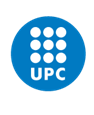

**ESTRUCTURES AEROESPACIALS**

# **Deployable solar array**

*February 2025*

**Julen Aguilera, Sergio Sanz**

**[Note: The assignment can be done in groups of two people.]**

## **Introduction**

The goal of this assignment is to study the structural response of a solar array panel of satellite orbiting Earth. Figure 1 shows a schematic representation of the panel’s structure modelled with two-dimensional bar elements. Nodes 1 and 2 act as a hinge, allowing the panel to be deployed. A sensor device of mass $M=$ 2 kg is attached at node 10. Material properties of the structural elements are given in Table 1. Notice that the outer frame (elements 1 to 9) and the inner bars (elements 10 to 17) are composed of different materials.

**Table 1**. Material properties.

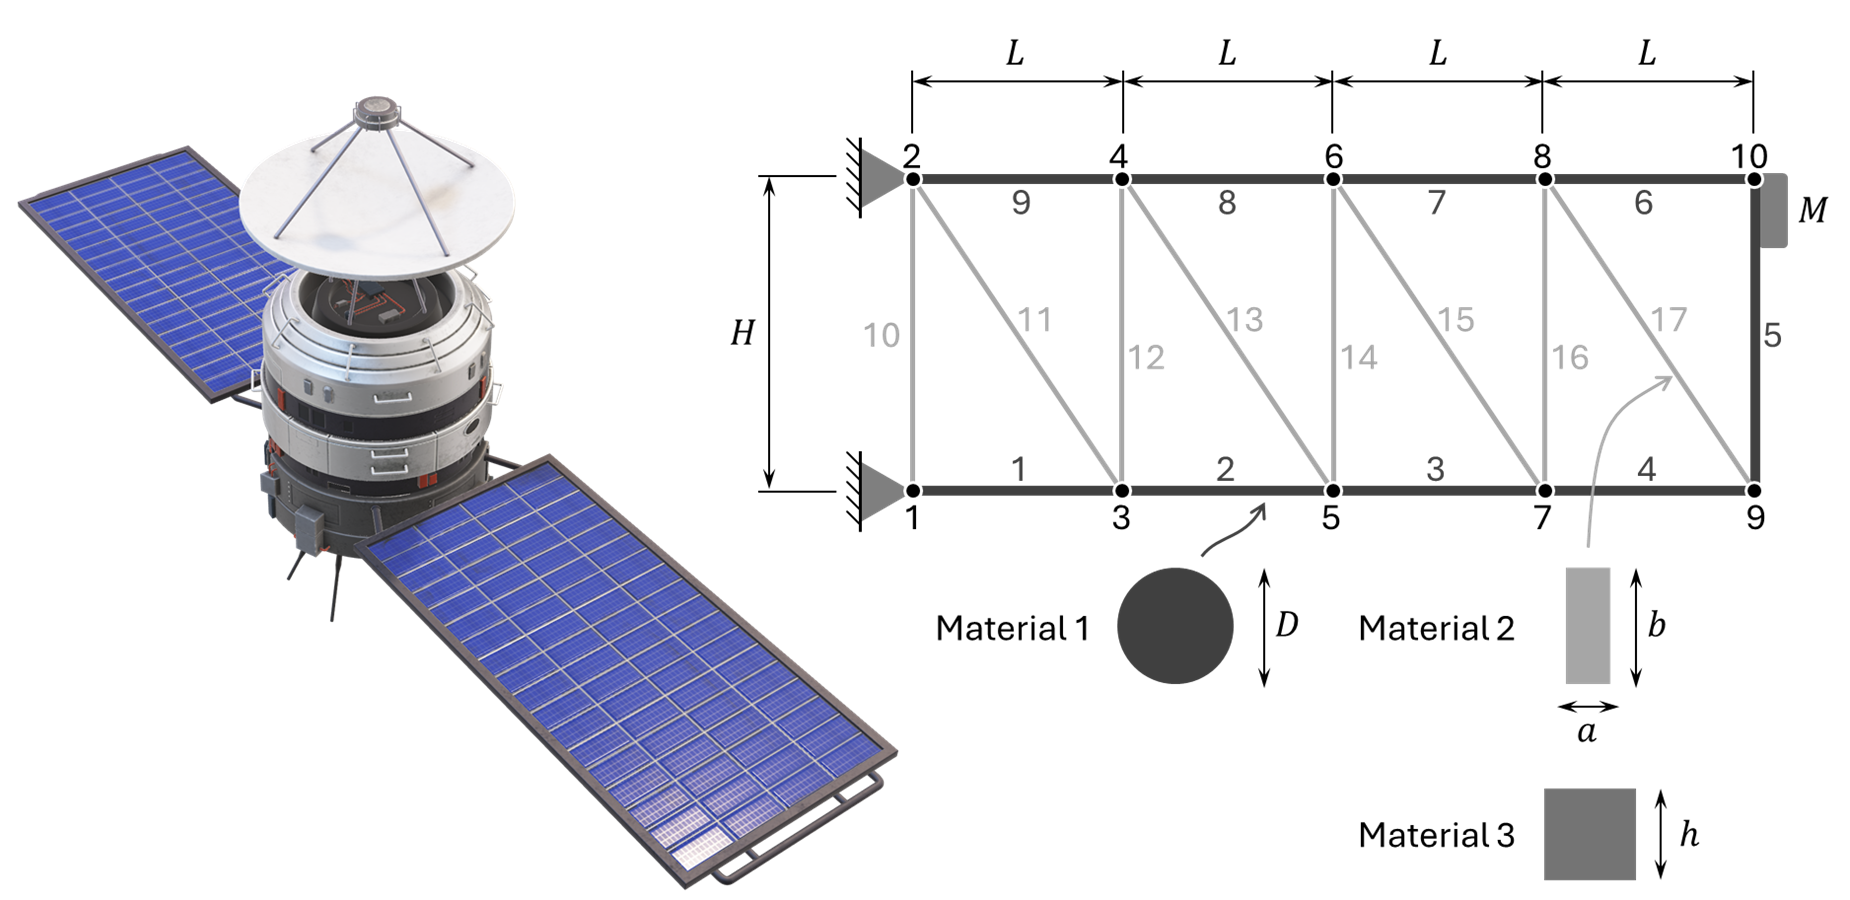

**Figure 1.** Schematic representation of the solar array structure. Data: $H=$ 1 m, $L=$ 0.75 m, $D=$ 20 mm, $a=$ 2.5 mm, $b=$ 10 mm, $h=$ 5 mm.

Two situations will be studied:

- Solar array panel deployment. Consider the panel is deployed in orbit at a speed of $\Omega=$ 10 rpm, inducing inertial loads caused by centrifugal forces.

- Extreme temperature changes. With the solar array already deployed, when the satellite enters the Earth's shadow zone, it experiences a sudden temperature decrease of $\Delta T=$ -120 K. In contrast, upon leaving the Earth's shadow zone, a temperature increase of $\Delta T=$ 120 K is produced.

For each scenario, the following is asked: 

- Plot of the deformed structure and stress-state of each element.

- Risk of buckling assessment. 

Discuss the results and justify which material would you choose for the inner structure.

Note: The critical stress for buckling is given by


$$\sigma_\text{cr}= \frac{\pi^2EI}{l^2A$$


where $l$ is the bar's length, $A$ is the cross-section's area, and $I$ is its second moment of area.

## Results

[Add here a brief explanation of how to obtain the loads acting on the structure and the code to produce the requested results]

Las cargas que actúan en la estructura se han calculado para cada nodo. 

En el primer caso, como el panel solar está haciendo un movimiento circular, las fuerzas que esto genera se pueden calcular a partir de la siguiente ecuación:


$$F_{i\;} =-m_i \cdot a_{i\;} =-m_{i\;} \cdot \left(-\Omega^2 \cdot r_i \right)$$


$F_{i\;}$es la fuerza asociada al nodo $i$; $m_{i\;}$es la masa asociada al nodo $i$, que ha sido calculada repartiendo la masa de cada barra entre los dos nodos que la definen; $\Omega$ es la velocidad de giro y $r_i$ es el radio de giro, en este caso, la distancia entre el nodo $i$ y visagra.

En el segundo caso, no hay ningún movimiento, pero hay un gradiente de temperaturas. Esto genera una tensión $\sigma_0 \;$que se puede calcular como: $\sigma_0 =-E{\cdot \varepsilon }_0 =-E\cdot \alpha_e \cdot \Delta T$; donde $E$ y $\alpha_e$ son el módulo de Young y el coeficiente de expansión térmica del material respectivamente y $\Delta T$ es el gradiente de temperatura.

La fuerza que esta tensión genera en cada elemento se calcula como:

$F_e =-\;\sigma_0 \cdot A_e$ ; donde $A_e$ es el área de la sección del elemento.

A continuación se muestra el código que permite visualizar la deformación y los esfuerzos en la estructura, así como calcular si se supera o no la tensión crítica de pandeo. Hay que seleccionar el material de las barras interiores (2 o 3) y el código mostrará los resultados para el primer caso, el despliegue del panel solar, y el segundo caso, la variación brusca de temperatura, con un gradiente positivo, y con un gradiente negativo.

clear % Clear workspace

% ---------- INSERTAR MATERIAL PARA EL ANÁLISIS ESTRUCTURAL-----------------

data.Mint = 2; % definir el material de las barras interiores (2 o 3)

% --------------------------------------------------------------------------

if all(data.Mint ~= [2, 3])
    error('Seleccionar material válido para las barras interiores');
end

% DATOS DEL PROBLEMA

data.L = 0.75;   % (m)
data.H = 1;      % (m)
data.D = 0.02;   % (m)
data.a = 0.0025; % (m)
data.b = 0.01;   % (m)
data.h = 0.005;  % (m)

data.A1 = pi*(data.D/2)^2;  % Área de círculo (m^2)
data.A2 = data.a*data.b;    % Área rectangular (m^2)
data.A3 = data.h*data.h;    % Área cuadrada (m^2)

data.ro1 = 2500;  % Densidad 1 (kg/m^3)
data.ro2 = 1200;  % Densidad 2 (kg/m^3)
data.ro3 = 2000;  % Densidad 3 (kg/m^3)

data.E1 = 5000e6; % Módulo de Young 1 (Pa = N/m^2)
data.E2 = 2000e6; % Módulo de Young 2 (Pa)
data.E3 = 1500e6; % Módulo de Young 3 (Pa)

data.alpha1 = 1e-6; % Coeficiente de expansión térmica 1 (1/K)
data.alpha2 = 1e-7; % Coeficiente de expansión térmica 2 (1/K)
data.alpha3 = 1e-7; % Coeficiente de expansión térmica 3 (1/K)

data.omega = 10*2*pi/60; % Velocidad angular (rad/s)
data.M = 2;  % Masa (kg)

data.inercia = [pi*data.D/64, data.a^3*data.b/12, data.h^4/12]; % Inercia (m^4)
%Para la inercia del segundo material se ha escogido la combinación que da
%inercia mínima, ya que es la que nos permite obtener el caso más perjudicial 
% para la barra: Iy

data.areas = [data.A1 data.A2 data.A3];

data.nnod = 10;
data.ni = 2;
data.nel = 17;
data.nne = 2;
data.ndof = data.nnod * data.ni;
data.nde = data.nne * data.ni;

% -------------------------- CASO 1----------------------------
data.caso=1; 
[xnod,Tnod,mat,Tmat,fixnod,fdata,data] = preproc(data);                     % Función que define los datos iniciales para el caso seleccionado
[disp,reac,stress,data] = solver(data,xnod,Tnod,mat,Tmat,fixnod,fdata);     % Función que calcula las tensiones, los desplazamientos y las reacciones

fint =    -5.1528   -4.6636   -3.6853   -2.2179         0   -8.4422   -9.9096  -10.8879  -11.3770         0   -0.0000         0   -0.0000         0   -0.0000         0   -0.0000
         0         0         0         0    0.0000         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    5.1528    4.6636    3.6853    2.2179         0    8.4422    9.9096   10.8879   11.3770         0    0.0000         0    0.0000         0    0.0000         0    0.0000
         0         0         0         0   -0.0000         0         0         0         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


pandeo_analisis (data,stress,xnod,Tnod,mat)                                 % Función que calcula si se superará o no la tensión crítica de pandeo

El material 2 no se romperá por pandeo


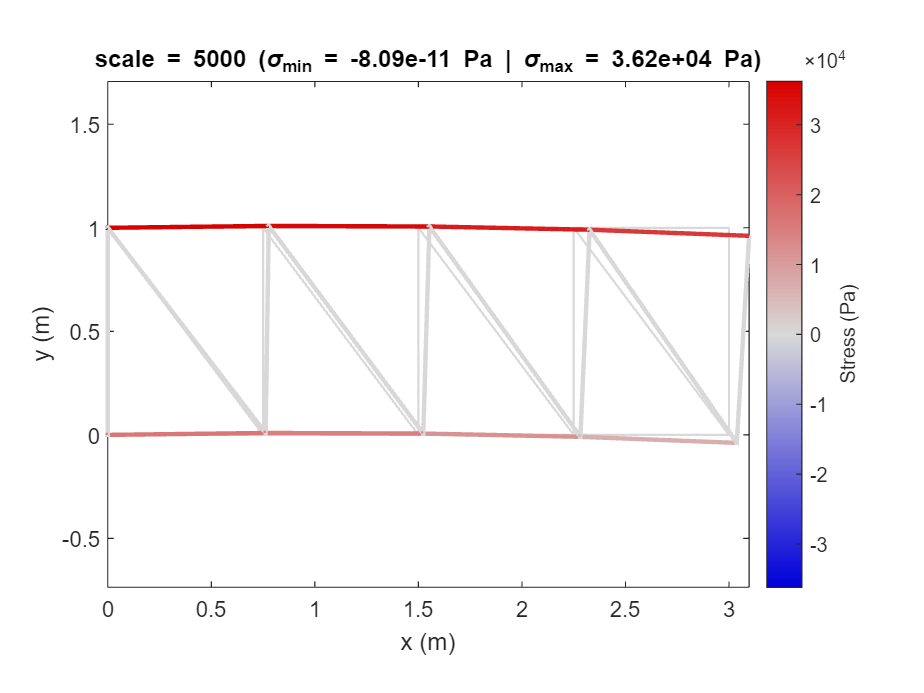

esfuerzos(:,1) = stress;
desplazamientos(:,1) = disp;
reacciones(:,1) = reac;
scale = 5000;
units = 'Pa';
plot2DBars(xnod,Tnod,disp,stress,scale,units)

% ------------------- CASO 2: Variación positiva -------------------------------
data.caso=2; 
data.deltaT = 120; % (K) Vaiación de temperatura 
[xnod,Tnod,mat,Tmat,fixnod,fdata,data] = preproc(data);
[disp,reac,stress,data] = solver(data,xnod,Tnod,mat,Tmat,fixnod,fdata);

fint =  -188.4956 -188.4956 -188.4956 -188.4956         0 -188.4956 -188.4956 -188.4956 -188.4956         0   -0.3600         0   -0.3600         0   -0.3600         0   -0.3600
         0         0         0         0 -188.4956         0         0         0         0         0    0.4800   -0.6000    0.4800   -0.6000    0.4800   -0.6000    0.4800
  188.4956  188.4956  188.4956  188.4956         0  188.4956  188.4956  188.4956  188.4956         0    0.3600         0    0.3600         0    0.3600         0    0.3600
         0         0         0         0  188.4956         0         0         0         0         0   -0.4800    0.6000   -0.4800    0.6000   -0.4800    0.6000   -0.4800


pandeo_analisis (data,stress,xnod,Tnod,mat)

EL MATERIAL 2 SE ROMPERÁ POR PANDEO!!


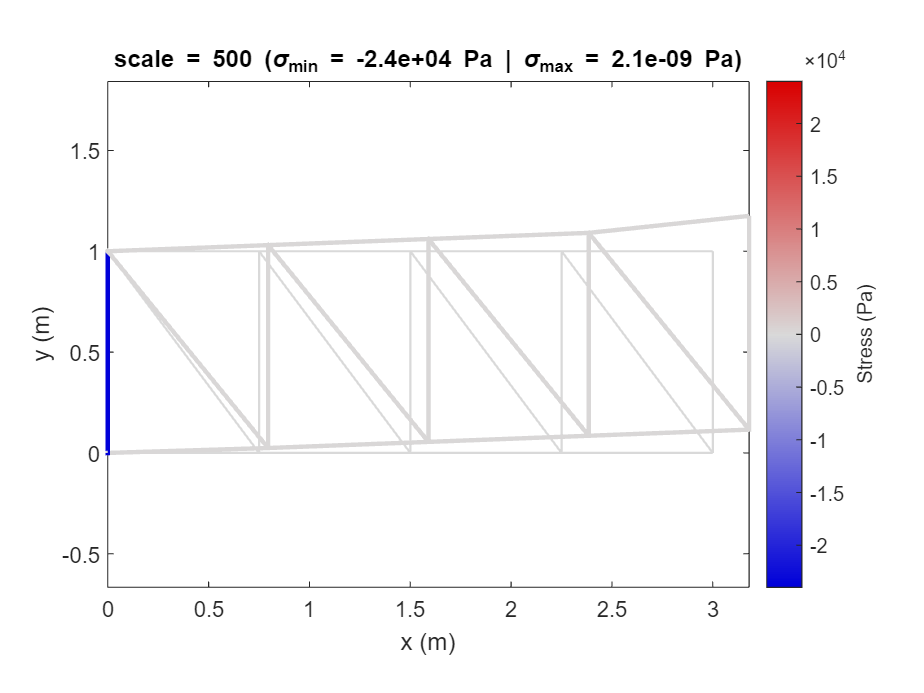

esfuerzos(:,2) = stress;
desplazamientos(:,2) = disp;
reacciones(:,2) = reac;

scale = 500;
units = 'Pa';
plot2DBars(xnod,Tnod,disp,stress,scale,units)

% ------------------- CASO 2: Variación negativa -------------------------------
data.caso=2; 
data.deltaT = -120; % (K) Vaiación de temperatura 
[xnod,Tnod,mat,Tmat,fixnod,fdata,data] = preproc(data);
[disp,reac,stress,data] = solver(data,xnod,Tnod,mat,Tmat,fixnod,fdata);

fint =   188.4956  188.4956  188.4956  188.4956         0  188.4956  188.4956  188.4956  188.4956         0    0.3600         0    0.3600         0    0.3600         0    0.3600
         0         0         0         0  188.4956         0         0         0         0         0   -0.4800    0.6000   -0.4800    0.6000   -0.4800    0.6000   -0.4800
 -188.4956 -188.4956 -188.4956 -188.4956         0 -188.4956 -188.4956 -188.4956 -188.4956         0   -0.3600         0   -0.3600         0   -0.3600         0   -0.3600
         0         0         0         0 -188.4956         0         0         0         0         0    0.4800   -0.6000    0.4800   -0.6000    0.4800   -0.6000    0.4800


pandeo_analisis (data,stress,xnod,Tnod,mat)

El material 2 no se romperá por pandeo


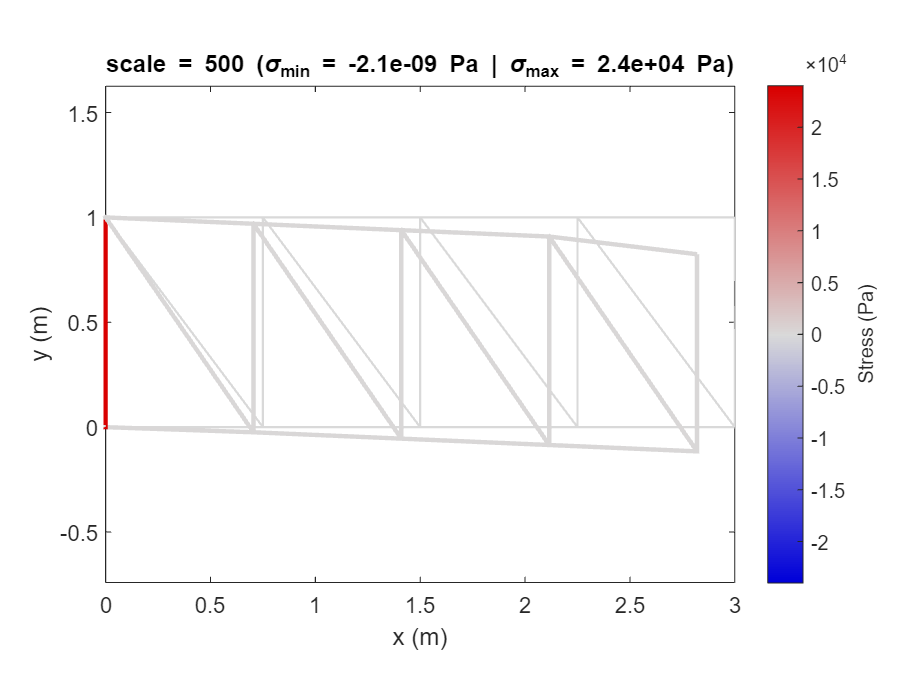

esfuerzos(:,3) = stress;
desplazamientos(:,3) = disp;
reacciones(:,3) = reac;

scale = 500;
units = 'Pa';
plot2DBars(xnod,Tnod,disp,stress,scale,units)

## Discussion

Durante el despliegue del panel solar, las barras exteriores, de material 1, trabajan a tracción, mientras que las barras interiores prácticamente no sufren ningún estrés, por lo que cualquiera de los dos materiales sería válido. 

Los cambios bruscos de temperatura hacen que las barras tiendan a dilatarse para una variación positiva de temperatura y comprimirse para una variación negativa. En el caso de una variación positiva, como los nodos de la barra 10 están fijos y no pueden dilatarse se genera una tensión que comprime la barra. Cuando la variación es negativa, la barra tiende a comprimirse, pero, como los desplazamientos de sus nodos están fijados, la barra tiene que soportar un esfuerzo de tracción.

En ninguno de los casos, para cualquiera de los materiales, las tensiones que aparecen superan el límite elástico. Sin embargo, la tensión crítica de pandeo si que se supera con el material 2 cuando la variación de temperatura es positiva. El material 3 no supera la tensión critica y podría aguantarlo.

Por lo tanto, después del análisis estructural de las dos situaciones planteadas, el despliegue del panel solar y los cambios bruscos de temperatura al entrar y salir de la zona de sombra de la Tierra, podemos concluir que el material adecuado para la estructura del panel solar es el material 3. 

## Code functions

1) ***Preprocess*** function:

function [xnod,Tnod,mat,Tmat,fixnod,fdata,data] = preproc(data)

% Nodal coordinates
xnod = [
    0,          0;
    0,          data.H;
    data.L,     0;
    data.L,     data.H;
    2*data.L,   0;
    2*data.L,   data.H;
    3*data.L,   0;
    3*data.L,   data.H;
    4*data.L,   0;
    4*data.L,   data.H;
];

% Nodal connectivities
Tnod = [
    1,3;
    3,5;
    5,7;
    7,9;
    9,10;
    8,10;
    6,8;
    4,6;
    2,4;
    1,2;
    2,3;
    3,4;
    4,5;
    5,6;
    6,7;
    7,8;
    8,9;
];

% Material properties: Modulo Young / Area seccion / Densidad / Coeficiente
% termico / Sigma_0
if data.caso == 1
    mat = [
    data.E1,data.A1,data.ro1,data.alpha1,0;
    data.E2,data.A2,data.ro2,data.alpha2,0;
    data.E3,data.A3,data.ro3,data.alpha3,0;
];
elseif data.caso == 2
    mat = [
    data.E1,data.A1,data.ro1,data.alpha1,-data.E1*data.alpha1*data.deltaT;
    data.E2,data.A2,data.ro2,data.alpha2,-data.E2*data.alpha2*data.deltaT;
    data.E3,data.A3,data.ro3,data.alpha3,-data.E3*data.alpha3*data.deltaT;
];
else 
    error('Seleccionar caso adecuado')
end

% Material connectivities
Tmat = [
    1;
    1;
    1;
    1;
    1;
    1;
    1;
    1;
    1;
    data.Mint;
    data.Mint;
    data.Mint;
    data.Mint;
    data.Mint;
    data.Mint;
    data.Mint;
    data.Mint;
];

% Fix nodes data
fixnod = [
    1,1,0;
    1,2,0;
    2,1,0;
    2,2,0;
];

long = longitud_elementos(data, xnod, Tnod);
masanod = masas_nodos(data,mat,Tmat, Tnod,long);
masanod(1,10) = masanod(1,10) + data.M;

% Point forces data
fdata = zeros(data.nnod,3);
if data.caso == 1
for i = 1:data.nnod
    fdata(i,1) = i;
    fdata(i,2) = 1;
    fdata(i,3) = data.omega*xnod(i,1)*masanod(1,i);
end
end

end

2) ***Solver*** function:

function [disp,reac,stress,data] = solver(data,xnod,Tnod,mat,Tmat,fixnod,fdata)

len = longitud_elementos(data, xnod, Tnod);             % Función que devuelve un vector con las longitudes
Kel = zeros(data.nde, data.nde, data.nel);              % Inicializa las matrices de rigidez elemental
fel = zeros(data.nde, data.nel);                        % Inicializa los vectores de fuerza de los elementos
R = zeros(4,4,data.nel);                                % Inicializa las matrices de transformación elementales
K = zeros(data.ndof); f = zeros(data.ndof,1);           % Inicializa la matriz global y el vector de fuerzas global

for i = 1:data.nel
    c = ((xnod(Tnod(i,2),1))-(xnod(Tnod(i,1),1)))/len(i);
    s = ((xnod(Tnod(i,2),2))-(xnod(Tnod(i,1),2)))/len(i);
    
    A = [c s; -s c];
    R(:,:,i) = [A, zeros(2); zeros(2), A];  % Matrices de transformación elementales

    B = [1 0 -1 0; 0 0 0 0; -1 0 1 0; 0 0 0 0;];
    fel(:,i) = - mat(Tmat(i,1),5) * mat(Tmat(i,1),2) * R(:,:,i).'*[-1 0 1 0].'; % Vector de fuerza del elemento
    Kel(:,:,i) = mat(Tmat(i,1),1) * mat(Tmat(i,1),2) / len(i) * R(:,:,i).'* B * R(:,:,i); % Matriz de rigidez elemental
end

Tdof = data.ni*(repelem(Tnod,1,data.ni)-1) + repmat(1:data.ni,size(Tnod)); % Matriz que guarda la información de los grados de libertad asociados a cada elemento

% Ensamblaje de la Matriz de rigidez global
for e = 1:data.nel
    I = Tdof(e,:);
    f(I) = f(I) + fel(:,e);
    K(I,I) = K(I,I) + Kel(:,:,e);
end

% Ensamblaje del vector de fuerzas global
for i = 1:length(fdata)
    I = data.ni * (i-1) + 1;    
    f(I) = f(I) + fdata(i,3);
end


u = zeros(data.ndof,1); 
vr = zeros(size(fixnod,1), 1);
 
for i = 1:length(fixnod)
    I = data.ni*(fixnod(i,1)-1) + fixnod(i,2);
    vr(i) = I;
    u(I) = fixnod(i,3);
end

vf = setdiff(1:data.ndof,vr);
u(vf) = K(vf,vf)\(f(vf)-K(vf,vr)*u(vr));
r= K(vr,:)*u-f(vr);
disp = u;
reac = r;

uel=zeros(data.nde,1,data.nel); % Inicializa el vector de desplazamientos global para cada elemento
uel_prima = zeros(data.nde,1,data.nel); % Inicializa el vector de desplazamientos local para cada elemento
strain = zeros(data.nel,1); % Inicializa el vector de deformaciones
stress = zeros(data.nel,1); % Inicializa el vector de tensiones


for e = 1:data.nel
    I = Tdof(e,:);
    uel(:,1,e) = u(I);
    uel_prima(:,1,e) = R(:,:,e)*uel(:,:,e);
    strain(e,1) = (uel_prima(3,1,e)-uel_prima(1,1,e))/len(e);
    stress(e,1) = strain(e,1)*mat(Tmat(e),1)+mat(Tmat(e),5);
end

fint = zeros(4, data.nel); % una columna por elemento
for e = 1:data.nel
    I = Tdof(e,:);           % DOFs del elemento e (6 valores)
    fint(:,e) = Kel(:,:,e) * u(I);  % resultado es 6x1, lo guardas en columna e
end
fint
end

*3) Cálculo de las longitudes de los elementos *

function [long] = longitud_elementos(data, xnod, Tnod)
for i= 1:data.nel
    long(i)=sqrt(((xnod(Tnod(i,2),1))-(xnod(Tnod(i,1),1)))^2+((xnod(Tnod(i,2),2))-(xnod(Tnod(i,1),2)))^2);
end
end

*4) Cálculo de masas de los nodos *

function [masanod] = masas_nodos(data, mat, Tmat, Tnod, long)
masael = zeros(1,data.nel);     % Inicializa una matriz con las masas de cada elemento
masanod = zeros(1,data.nnod);   % Inicializa una matriz con las masas de cada nodo
for i=1:data.nel
    masael(1,i) = mat(Tmat(i),2)*mat(Tmat(i),3)*long(i);
    for j =1:2
        masanod(Tnod(i,j)) = masanod(Tnod(i,j)) + masael(i)/2; % Suma la mitad de la masa de un elemento en cada uno de los nodos que lo forman
    end
end
end


*5) Analizar pandeo *

function pandeo_analisis (data,stress,xnod,Tnod,mat)
if min(stress) < 0 
[stress_max, elemento_critico] = min(stress); % Calcula el valor de la tensión mínima (compresión máxima) y el índice del elemento que la está soportando
stress_max = abs(stress_max);
long = longitud_elementos(data, xnod, Tnod);
sigma_pandeo = pi^2*mat(data.Mint,1)*data.inercia(data.Mint)/long(elemento_critico)^2/mat(data.Mint,2); % Cálculo de la tensión crítica de pandeo
   if sigma_pandeo <= stress_max
    fprintf('EL MATERIAL %.0f SE ROMPERÁ POR PANDEO!!\n', data.Mint);
   else
    fprintf('El material %.0f no se romperá por pandeo\n', data.Mint);
   end
else
    fprintf('El material %.0f no se romperá por pandeo\n', data.Mint);
end
end

Use the following function to plot the deformed structure. Pay attention to the inputs:

- `disp` is a vertical vector containing all degrees of freedom (displacements).

- `stress` is a vertical vector containing the stress of each element.

- `scale` is a scaling factor to amplify the displayed deformed (e.g., setting `scale=100` will show the structure 100 times more deformed that the actual deformation values).

- `units` can be used to specify the units in which the stresses are given (e.g., set `units='Pa'` is the values in stress are given in Pa, or `units='MPa'` if they are given in MPa).

function plot2DBars(xnod,Tnod,disp,stress,scale,units)

% Precomputations
X = xnod(:,1);
Y = xnod(:,2);
Ux = scale*disp(1:2:end,1);
Uy = scale*disp(2:2:end,1);
smin = min(stress);
smax = max(stress);

% Open plot window
figure; box on; hold on; axis equal;

% Plot undeformed structure
plot(X(Tnod'),Y(Tnod'),'-', ...
    'Color',0.85*[1,1,1],'LineWidth',1);

% Plot deformed structure with colorbar for stresses 
patch(X(Tnod')+Ux(Tnod'),Y(Tnod')+Uy(Tnod'),[stress';stress'], ...
    'EdgeColor','interp','LineWidth',2);

% Colorbar settings
clims = get(gca,'clim');
clim(max(abs(clims))*[-1,1]);
n = 128; % Number of rows
c1 = 2/3; % Blue
c2 = 0; % Red
s = 0.85; % Saturation
c = hsv2rgb([c1*ones(1,n),c2*ones(1,n);1:-1/(n-1):0,1/n:1/n:1;s*ones(1,2*n)]');
colormap(c); 
cb = colorbar;

% Add labels
title(sprintf('scale = %g (\\sigma_{min} = %.3g %s | \\sigma_{max} = %.3g %s)',scale,smin,units,smax,units)); 
xlabel('x (m)'); 
ylabel('y (m)');
cb.Label.String = sprintf('Stress (%s)',units); 

end